clc,clear,close all
global Element
global hstep
num = 20;
Num = num+2;
left = 0;
right = 2;
hstep = (right-left)/num;
Element = [left-hstep:hstep:right;left:hstep:right+hstep]';
time = 0.1;
U = zeros(num+2,3,3); % n+2 个区间，3个分量，2阶多项式
now = 0;
dt = 0.001;

% 初始化
for i = 2:num+1
    a = Element(i,1);
    b = Element(i,2);
    U(i,1,1) = quadgk(@(x) u1(x).*basefun0(x,a,b),a,b)/hstep;
    U(i,1,2) = quadgk(@(x) u1(x).*basefun1(x,a,b),a,b)/hstep^2;
    U(i,1,3) = quadgk(@(x) u1(x).*basefun2(x,a,b),a,b)/hstep^3;

    U(i,2,1) = quadgk(@(x) u2(x).*basefun0(x,a,b),a,b)/hstep;
    U(i,2,2) = quadgk(@(x) u2(x).*basefun1(x,a,b),a,b)/hstep^2;
    U(i,2,3) = quadgk(@(x) u2(x).*basefun2(x,a,b),a,b)/hstep^3;

    U(i,3,1) = quadgk(@(x) u3(x).*basefun0(x,a,b),a,b)/hstep;
    U(i,3,2) = quadgk(@(x) u3(x).*basefun1(x,a,b),a,b)/hstep^2;
    U(i,3,3) = quadgk(@(x) u3(x).*basefun2(x,a,b),a,b)/hstep^3;
end

[U,Upm,m_Hflux] = SolveStep(U);
while now<time
    if now+dt>=time
        dt = time-now;
    end
    U = RK(U,dt);
    now = now+dt;
    now
end

now = 1.0000e-03

now = 0.0020

now = 0.0030

now = 0.0040

now = 0.0050

now = 0.0060

now = 0.0070

now = 0.0080

now = 0.0090

now = 0.0100

now = 0.0110

now = 0.0120

now = 0.0130

now = 0.0140

now = 0.0150

now = 0.0160

now = 0.0170

now = 0.0180

now = 0.0190

now = 0.0200

now = 0.0210

now = 0.0220

now = 0.0230

now = 0.0240

now = 0.0250

now = 0.0260

now = 0.0270

now = 0.0280

now = 0.0290

now = 0.0300

now = 0.0310

now = 0.0320

now = 0.0330

now = 0.0340

now = 0.0350

now = 0.0360

now = 0.0370

now = 0.0380

now = 0.0390

now = 0.0400

now = 0.0410

now = 0.0420

now = 0.0430

now = 0.0440

now = 0.0450

now = 0.0460

now = 0.0470

now = 0.0480

now = 0.0490

now = 0.0500

now = 0.0510

now = 0.0520

now = 0.0530

now = 0.0540

now = 0.0550

now = 0.0560

now = 0.0570

now = 0.0580

now = 0.0590

now = 0.0600

now = 0.0610

now = 0.0620

now = 0.0630

now = 0.0640

now = 0.0650

now = 0.0660

now = 0.0670

now = 0.0680

now = 0.0690

now = 0.0700

now = 0.0710

now = 0.0720

now = 0.0730

now = 0.0740

now = 0.0750

now = 0.0760

now = 0.0770

now = 0.0780

now = 0.0790

now = 0.0800

now = 0.0810

now = 0.0820

now = 0.0830

now = 0.0840

now = 0.0850

now = 0.0860

now = 0.0870

now = 0.0880

now = 0.0890

now = 0.0900

now = 0.0910

now = 0.0920

now = 0.0930

now = 0.0940

now = 0.0950

now = 0.0960

now = 0.0970

now = 0.0980

now = 0.0990

now = 0.1000

xx = linspace(left,right,num+1);


syms xi
for i = 1:length(xx)
    x = xx(i);
    xii = vpasolve(xi-x+u1(xi)*time);
    yy1(i) = computeU1(U,i,x);
    yy2(i) = double(u1(xii));
end




xx = mean(Element,2);
uu = zeros(Num,3);
for i = 1:Num
    x = xx(i);
    uu(i,1) = computeU1(U,i,x);
    uu(i,2) = computeU2(U,i,x);
    uu(i,3) = computeU3(U,i,x);
end




## 测试区间

% plot(Upm(:,3,1))
% hold on
% plot(Upm(:,3,2))
% hold off

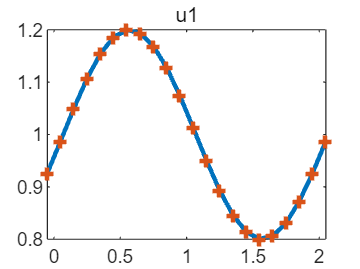



t = time;
plot(xx,uu(:,1),'LineWidth',2)
hold on
plot(xx,1+0.2*sin(pi*(xx-0.7*t)),'+','LineWidth',2);
hold off
title('u1')

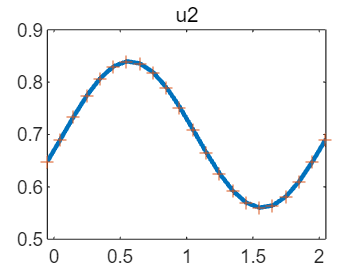


plot(xx,uu(:,2),'LineWidth',2)
hold on
plot(xx,0.7+0.14*sin(pi*(xx-0.7*t)),'+');
hold off
title('u2')

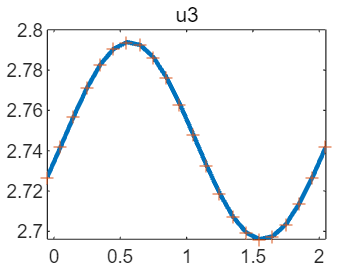


plot(xx,uu(:,3),'LineWidth',2)
hold on
plot(xx,2.745+0.049*sin(pi*(xx-0.7*t)),'+')
hold off
title('u3')